# **Ejercicio 3**

## T5.3 Polinomio de interpolación de Lagrange

#### Grupo 8: Ana Robledano Abasolo, Alfredo Robledano Abasolo, 

#### Melani Tatayo Culchas, Rubén Sierra Serrano

a) Desarrollar una función en Matlab que interpole un conjunto de puntos utilizando un polinomio de Lagrange. La función debe tener la forma:

`Yint=LagINT(x,y,Xint)`

La entrada de la función son las coordenadas de los puntos de datos dados (`x,y`) y la coordenada `Xint `en el punto en el que se debe calcular el valor interpolado de y. La salida de la función es el valor interpolado de y, `Yint.`

b) Se da el conjunto de los siguientes cinco puntos de datos:

Emplear la función creada para representar gráficamente el polinomio de interpolación y los puntos dados. Calcular el valor interpolado en $x=3$.

Preparamos el entorno de trabajo

clear
clc
close all

Zona de declaración de variables

x = [1 2 4 5 7];
y = [52 5 -5 -40 10];
Xint = 3;

Llamamos a la función y mostramos el resultado

Yint = LagINT(x,y,Xint);
fprintf("El punto de interpolación obtenido en x = 3 toma el valor: %.3f",Yint)

El punto de interpolación obtenido en x = 3 toma el valor: 6.000

Acomodamos los vectores para poder representar gráficamente el polinomio de interpolación 

xx = linspace(min(x),max(x));
yy = zeros(size(xx));
for i=1:length(xx)
    yy(i) = LagINT(x,y,xx(i));
end

Representación gráfica

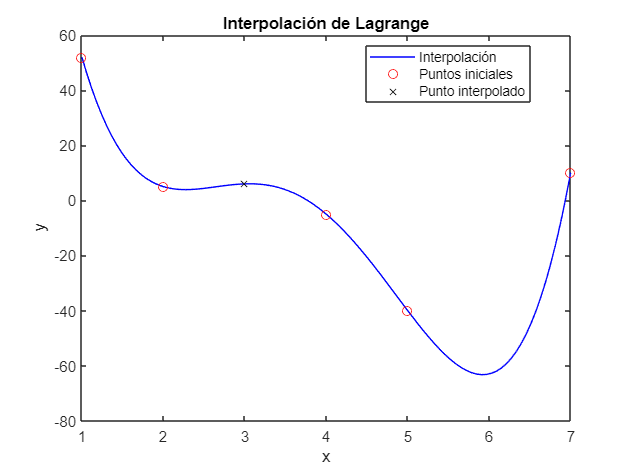

plot(xx,yy,"b-",x,y,"ro",Xint,Yint,"kx");
legend("Interpolación","Puntos iniciales","Punto interpolado","Location","best");
xlabel("x");
ylabel("y");
title("Interpolación de Lagrange");